# Adaptive Model Predictive Control for Leukemia Treatment

Note: changing theta 6 and 9 seem to have the largest impact on outcome

- theta 6's initial guess can't be too far away from the actual value

- theta 9 is very sensitive, I noticed that when it was initialized to something lower than the actual value, it had a really hard time predicting the true value, but it could handle initial values much greater than the true value.

- sometimes it's not the problem that they don't uncover the correct value, but they impact the other parameters (e.g. increasing theta 9's value too high causes theta 8 to converge to the wrong value)

Note: algorithm doesn't handle input or output noise very well

- adding process noise to the model e.g. replacing jost_discrete with jost_noisy for all functions makes it diverge from the nominal trajectory a lot

- adding measurement noise (to y_k_obs in calc_params function) is a bit better but still had a hard time converging to the optimal solution 

- adding noise to the nominal trajectory didn't make a big difference in performance, still tracked well! (tried with var_w = 0.01 and 0.025 with no problems, anything > 0.05 starts to look very different to the nominal trajectory)

- overall, the more noise, the longer it takes to converge

Note: points of weakness

- adding lower bound to calc_params fmincon (on line 123) causes the algorithm to break for some reason (I think it's because fmincon needs to go negative for it to arrive at the solution but not quite sure) 

- sometimes adding too much noise to nominal trajectory, measurement noise or process noise causes fmincon to explode (the error goes to infinity) - simulation won't finish 

clear all;
clc; 
close all; 

## Reading from DataSheet

Note: requires Data Sheet 1 and Data Sheet 2 from Jost to be in the same directory as this code. There may be a matlab warning when you read the files but it doesn't affect anything in the file data.

DataSheet1 = readmatrix("Data Sheet 1.csv");
DataSheet2 = readmatrix("Data Sheet 2.csv");

% Patients are numbered starting from 101 in the datasheet but for
% simplicity only put ids starting from 1 (e.g. 1 --> 101 in datasheet).
% If you enter -1, it uses population instead of patient parameters.
patientID = 1;

% population parameters (from Jost et al.)
population_params = [2.06; 0.146; 0.103; 0.866];
% change however you wish (see note above about theta 6 and 9)
population_params_guess = [0.75; 1.96; 1.35; 1.75]; %[2.15; 0.5; 0.25; 0.85];
population_bsa = 1.71; % Jost 2020 paper (Table 1, Body Surface Area range 0.47-1.98 m^2) - average population BSA

% get patient parameters
if patientID > 0
    p_actual = DataSheet1(patientID, 2:5)'; % turn into 4 by 1
    p_guess = population_params;
    
%     patient_data    = [];
%     patient_doses   = [];
%     patient_evid    = [];
    for k=1:length(DataSheet2)
        patient_id  = DataSheet2(k,1);
%         time        = DataSheet2(k,2);
%         measurement = DataSheet2(k,3);
%         dose        = DataSheet2(k,5);
%         evid        = DataSheet2(k,7);
%         
        if patient_id - 100 == patientID
            bsa = DataSheet2(k,11);
            break;
%             if DataSheet2(k,3) ~= 0
%                 patient_data = [patient_data; time measurement];
%             end
%             patient_doses = [patient_doses; time dose];
%             evid = [patient_evid; time evid];
        end
    end
%     figure()
%     hold on
%     xlabel('Days Elapsed')
%     ylabel('ANC / L blood')
%     title("ANC per L Blood vs Days Elapsed")
%     scatter(patient_data(:,1), patient_data(:,2), 'red','filled')
%     hold off
%     
%     figure()
%     hold on
%     xlabel('Days Elapsed')
%     ylabel('6-MP Drug Does (mg)')
%     title("Nominal Doses")
%     plot(patient_doses(:,1), patient_doses(:,2))
%     hold off
else
    p_actual = population_params;
    p_guess = population_params_guess;
    bsa = population_bsa;
end
clear population_bsa population_params_guess population_params
clear patient_id time measurement dose evid


## Initialization

theta = [ ...
    31.2; ...
    12.72; ...
    0.019; ...
    9.9216; ...
    0.219*(bsa^1.16); ...
    p_actual(1); ...
    p_actual(2); ...
    p_actual(3); ...
    p_actual(4); ...
    2.3765; ...
];

% initial values (from Jost et al.)
x0 = [0;...
    0;...
    0;...
    theta(6)*theta(10)/theta(7);...
    theta(6)*theta(10)/theta(7);...
    theta(6)*theta(10)/theta(7);...
    theta(6)*theta(10)/theta(7);...
    theta(6)];

N = 10; % number of cycles
N_cycledays = 21; % for Steve we use 21 days
N_drugdays = 21; % for Steve we use 14 days

% Dimension
n = 8; % dimension of state vector x 
m = 1; % dimension of observation vector y

step_size = 0.05;
num_tpts = N_cycledays/step_size + 1;
tspan = linspace(0, N_cycledays, num_tpts);

t_oncycle = N_drugdays/step_size;
t_offcycle = (N_cycledays-N_drugdays)/step_size;
t_fullcycle = t_oncycle + t_offcycle + 1;

lower = 1; upper = 2;
var_w = 0.025;

## Nominal Trajectory

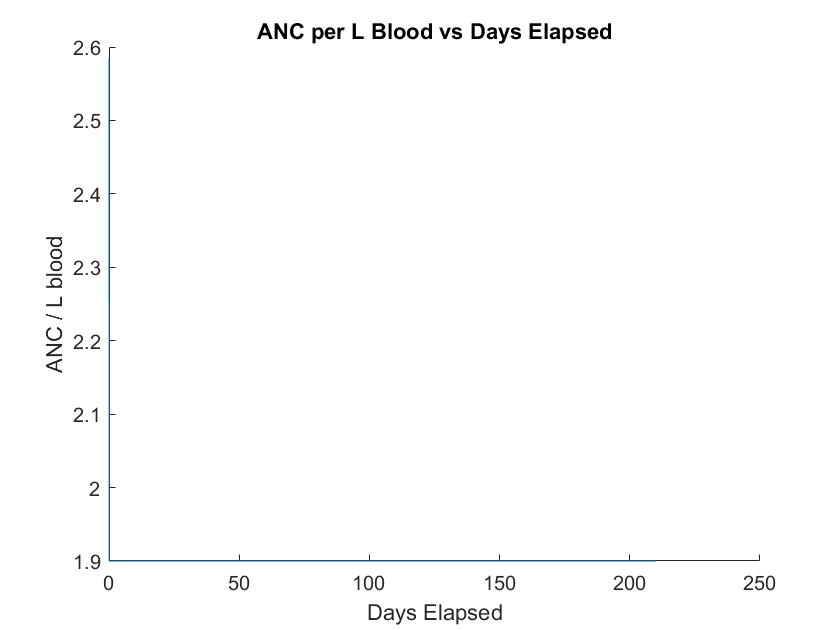

% Simulation Length
N_cyclestotal = N;
N_days=N_cycledays*N_cyclestotal;

t_s = step_size;
N_steps = N_days / t_s;
N_steps_per_day = 1 / t_s;
time = (0:t_s:N_days);

% Nominal trajectory with new time vector
x_nominal = zeros([N_steps+1 n]);
u_nominal = zeros([N_steps+1 1]);
rho = zeros([N_steps+1 m]);

u_k=50*bsa; % "50" comes from existing treatment
x_nominal(1,:) = x0;
rho(1,:) = g_nonlin(x0);

for k=1:N_days
    day_in_cycle = get_cycle_day(k, N_cycledays);
    for i=1:N_steps_per_day
        j = (N_steps_per_day*(k-1) + i);
        if day_in_cycle <= N_drugdays
          u_nominal(j,:) = u_k;
        end
%         x_nominal(j+1,:) = jost_discrete(...
%             (j+1)*t_s,x_nominal(j,:)',u_nominal(j,:),p_actual,N_cycledays,N_drugdays,t_s ...
%         );
        rho(j+1, :) = 1.9; %g_nonlin(x_nominal(j+1,:));
    end
    if day_in_cycle == N_cycledays
        x_k = rho(j+1,:);
        if x_k < lower
            u_k = 0.8*u_k;
        elseif x_k > upper
            u_k = 1.2*u_k;
        end
    end
end

figure()
hold on
xlabel('Days Elapsed')
ylabel('ANC / L blood')
title("ANC per L Blood vs Days Elapsed")
plot(time,rho)
hold off

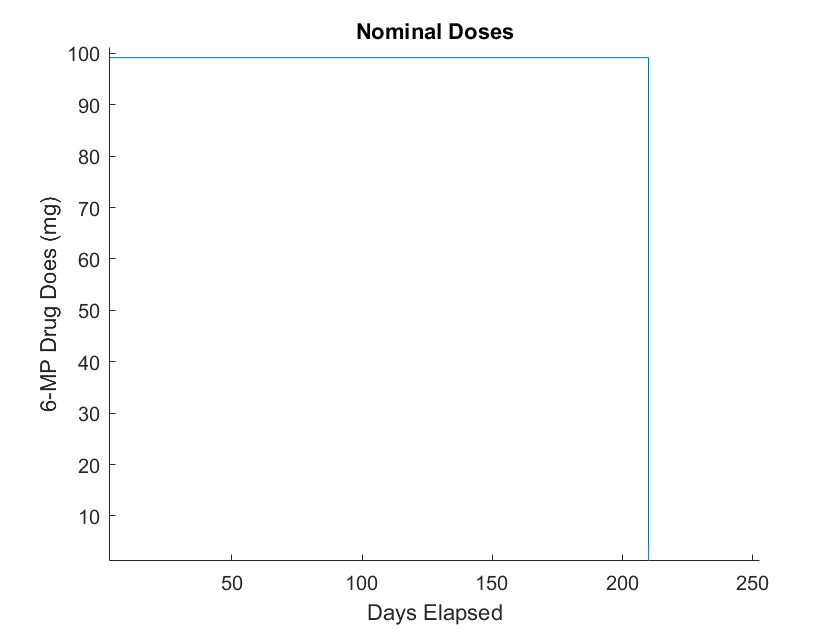


figure()
hold on
xlabel('Days Elapsed')
ylabel('6-MP Drug Does (mg)')
title("Nominal Doses")
plot(time,u_nominal)
hold off

## Adaptive Model Predictive Controller

N_cyclespred = 1; %floor(N/5);
N_dayspred=N_cycledays*N_cyclespred;

n_params = length(p_actual);
x_calc = zeros([n,1,N_steps+1]);
y_calc = zeros([m,1,N_steps+1]);
params_calc = zeros([n_params,1,N_cyclestotal+1]);
u_calc = zeros([1,N_days]);

x_calc(:,:,1) = x0;
y_calc(:,:,1) = g_nonlin(x0);

% using doses from standard practice

params_calc(:,:,1) = p_guess;

for k=0:N_cycledays:N_days-1
    prev_step = N_steps_per_day*k + 1;  
    cycle = floor(k/N_cycledays)+1;
    
    f = @(p)calc_params(p, p_actual, x0, u_calc, prev_step, N_cycledays, N_drugdays, t_s);
    [p_star, fval] = fmincon(f,params_calc(:,:,cycle));

%     calc_control(...
%         p_star, rho, x_calc(:,:,prev_step), k, u_nominal, 10, 0.0001, N_dayspred, ...
%         N_cyclespred, N_cycledays, N_drugdays, t_s ...
%     );
    
    g = @(u)calc_control(...
        p_star, rho, x_calc(:,:,prev_step), k, u, 10, 0.0001, N_dayspred, N_cyclespred, N_cycledays, N_drugdays, t_s ...
    );

    init_guess_u = 50*bsa;
    [u_star, gval] = fmincon(...
        g,repmat(init_guess_u, [N_cyclespred 1]), [], [], [], [], ...
        repmat(0.01, [N_cyclespred 1]), repmat(init_guess_u*2, [N_cyclespred 1])... % lower bound, upper bound
    );
    u_calc(k+1:k+N_drugdays) = u_star(1);

    params_calc(:,:,cycle+1) = p_star;
    
    for i=prev_step:prev_step + N_steps_per_day*N_cycledays - 1
        x_calc(:,:,i+1) = jost_discrete((i+1)*t_s,x_calc(:,:,i), u_star(1),p_actual,N_cycledays,N_drugdays,t_s);
        y_calc(:,:,i+1) = g_nonlin(x_calc(:,:,i+1));
    end
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


## Plots

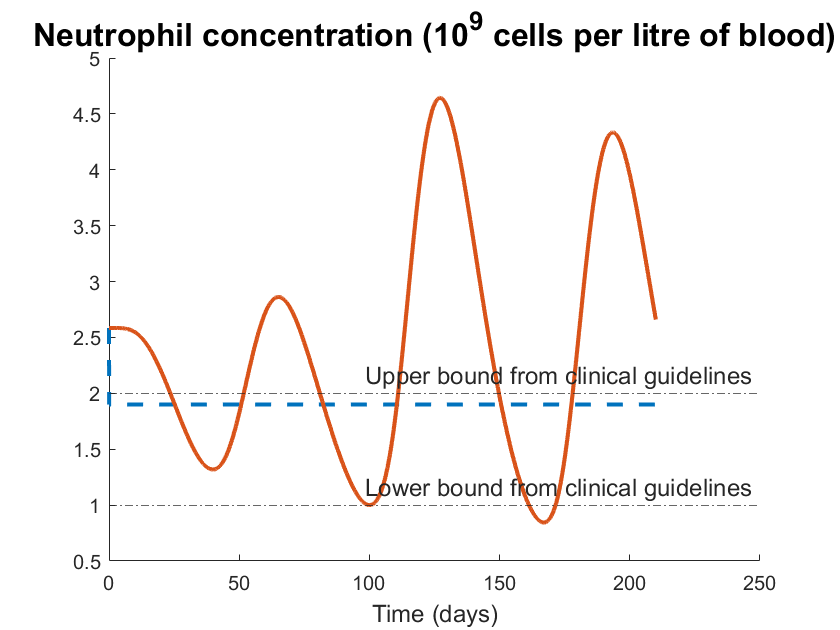

u_calc_full = zeros(size(u_nominal));
for k=1:N_days
    i = N_steps_per_day*(k-1);
    u_calc_full(i+1:i+N_steps_per_day,:) = u_calc(k)*(ones(N_steps_per_day,1));
end

y_neutrophils = reshape(y_calc(1,1,:),[1 N_steps+1]);
figure()
hold on
plot(time,rho, "LineStyle","--", "LineWidth", 2)
plot(time, y_neutrophils, "LineWidth", 2)
title('Neutrophil concentration (10^9 cells per litre of blood)', "FontSize", 16)
ub = yline(2, "-.", "Upper bound from clinical guidelines");
lb = yline(1, "-.", "Lower bound from clinical guidelines");
ub.FontSize = 12;
lb.FontSize = 12;
xlabel('Time (days)', "FontSize", 12)
ylabel('')
% ylim([0.95 2.25])
% lgd1 = legend(...
%     ' Desired neutrophil concentration',...
%     ' Neutrophil concentration using Jost et al. 2020 biochemical model and our proof-of-concept controller'...
% );
% lgd1.FontSize = 12;
gca.FontSize = 12;
hold off

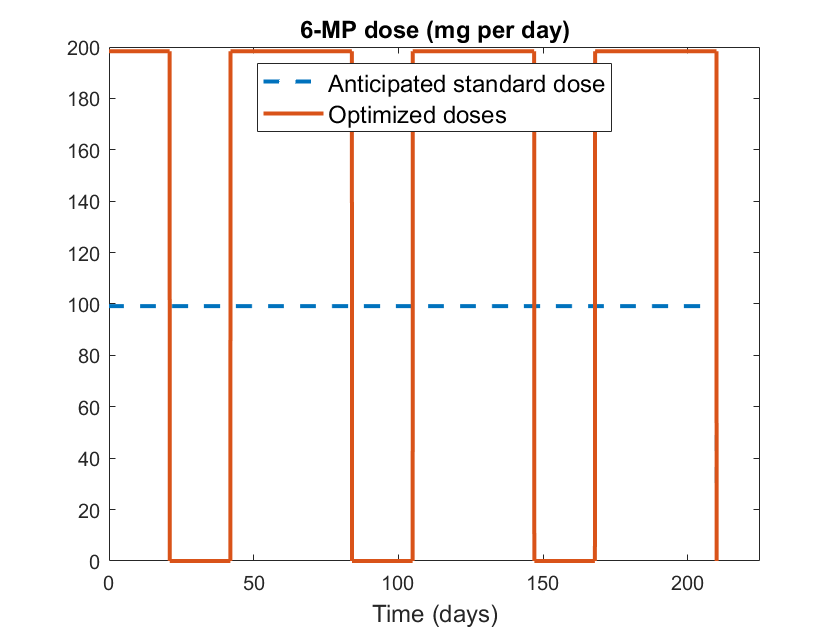


figure()
plot(time,u_nominal, "LineStyle", "--", "LineWidth", 2)
hold on
plot(time,u_calc_full, "LineWidth", 2)
title('6-MP dose (mg per day)', "FontSize", 12)
xlabel('Time (days)', "FontSize", 12)
ylabel('')
xlim([0 225])
l = legend('Anticipated standard dose','Optimized doses');
l.Location = "north";
l.FontSize = 12;
gca.FontSize = 12;
hold off

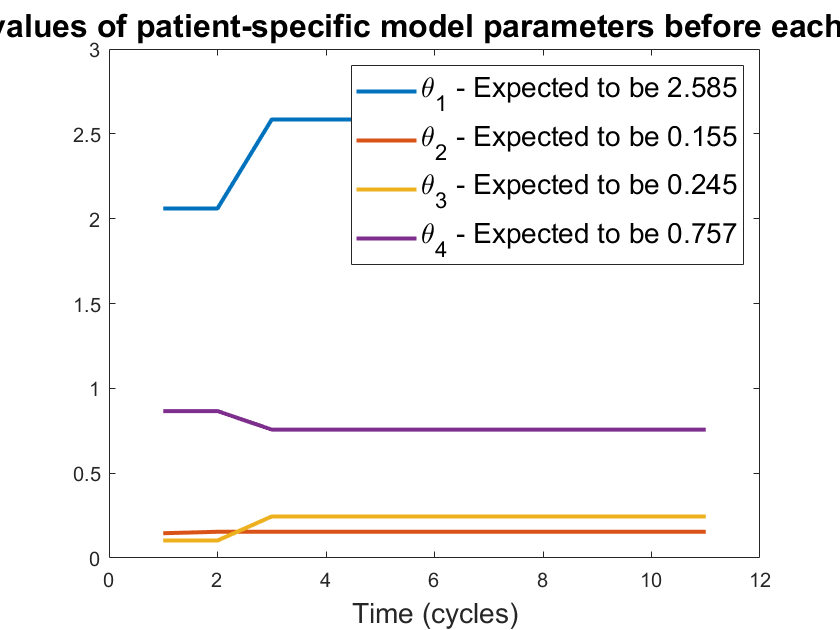


p1 = reshape(params_calc(1,1,:),[1 N_cyclestotal+1]);
p2 = reshape(params_calc(2,1,:),[1 N_cyclestotal+1]);
p3 = reshape(params_calc(3,1,:),[1 N_cyclestotal+1]);
p4 = reshape(params_calc(4,1,:),[1 N_cyclestotal+1]);
figure()
plot(p1, "LineWidth", 2)
hold on
plot(p2, "LineWidth", 2)
hold on
plot(p3, "LineWidth", 2)
hold on
plot(p4, "LineWidth", 2)
title('Estimated values of patient-specific model parameters before each 21-day cycle', "FontSize", 16)
xlabel('Time (cycles)', "FontSize", 14)
ylabel('')
lgd2 = legend(...
    sprintf('%s - Expected to be %0.3f', "\theta_1", p_actual(1)), ...
    sprintf('%s - Expected to be %0.3f', "\theta_2",p_actual(2)), ...
    sprintf('%s - Expected to be %0.3f', "\theta_3",p_actual(3)), ...
    sprintf('%s - Expected to be %0.3f', "\theta_4",p_actual(4)) ...
);
lgd2.FontSize = 14;
gca.FontSize = 12;
hold off

## Comparison to Kalman Filter Controller

Note: can only compare for 7 cycles because the kalman filter controller is only simulated for that long in the matlab workspace *kf_smoothed_data* file

figure()
hold on
xlabel('Days Elapsed')
ylabel('ANC (Number of cells / L blood)')
title("All Neutrophil Count (ANC) x_8 vs Days Elapsed")
plot(time, rho*1e9, "LineWidth", 1)
plot(t_smoothed_flattened,x_smoothed_flattened(:,8)*1e9, "LineWidth", 1)
plot(time, y_neutrophils*1e9, "LineWidth", 1, "Color", "#77AC30")
legend("Nominal", "KF Controller Smoothed", "Adaptive MPC")
hold off

figure()
plot(time,u_nominal, "LineWidth", 1)
hold on
plot(t, u_smoothed_flattened, "LineWidth", 1)
hold on
plot(time,u_calc_full, "LineWidth", 1, "Color", "#77AC30")
title('Control Input')
xlabel('Time')
ylabel('6-MP Drug Dose (mg)')
l = legend('nominal', "KF Controller generated", 'AMPC generated');
l.Location = "north";
hold off